## Maximum entropy and quantized metric models for absolute category ratings

Code for our paper "Maximum entropy and quantized metric models for absolute category ratings." 

- **Authors: **Saupe, D., Rusek, K., Hägele, D., Weiskopf, D., & Janowski, L.

- **Journal**: [IEEE Signal Processing Letters](http://ieeexplore.ieee.org/xpl/RecentIssue.jsp?punumber=97?source=authoralert)

- **Publication Date**: 2024

- **Volume**: 31 

- **On Page(s)**: 2970-2974

- **Print ISSN**: 1070-9908

- **Online ISSN**: 1558-2361

- **Digital Object Identifier**: [10.1109/LSP.2024.3480832](https://ieeexplore.ieee.org/document/10716765?source=authoralert)

- **Communicating author:** Dietmar Saupe, dietmar.saupe@uni-konstanz.de

Copyright (C) 2024 by Saupe, D., Rusek, K., Hägele, D., Weiskopf, D., & Janowski, L. <dietmar.saupe@uni-konstanz.de>

Permission to use, copy, modify, and/or distribute this software for any purpose with or without fee is hereby granted.

THE SOFTWARE IS PROVIDED "AS IS" AND THE AUTHOR DISCLAIMS ALL WARRANTIES WITH REGARD TO THIS SOFTWARE INCLUDING ALL IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS. IN NO EVENT SHALL THE AUTHOR BE LIABLE FOR ANY SPECIAL, DIRECT, INDIRECT, OR CONSEQUENTIAL DAMAGES OR ANY DAMAGES WHATSOEVER RESULTING FROM LOSS OF USE, DATA OR PROFITS, WHETHER IN AN ACTION OF CONTRACT, NEGLIGENCE OR OTHER TORTIOUS ACTION, ARISING OUT OF OR IN CONNECTION WITH THE USE OR PERFORMANCE OF THIS SOFTWARE.

The program reads either one of the two datasets KonIQ-10k or VQEG-HDTV and then computes the maximum entropy and quantized metric models for all the teh ACR distributions in the datasets. This reproduces (among other things) the values in the columns for AIC and G-test in Tables I and II.

clear; close all; clc;
rng (0);


## Select the model types for ACR probability distributions

% list of available ACR probability distribution types
dlist = ["normal", "logistic", "beta", "kumaraswamy", "logit-logistic", "maxentropy", "GSD"];
setGSD ("gsd_prob_vectors.csv");        % reads table for the GSD distribution
% select any subset of the model types for execution
dlist = ["normal", "logistic", "beta"];

## Select and import CSV file of an ACR dataset

csvlist = ["KonIQ-10k.csv", "VQEG-HDTV.csv"];  % list of ACR datasets
% column 1 = id of stimulus, cols 2:6 = the counts of the 5-level ACR ratings 1 to 5
csvfile = csvlist(1);        % choose one of the datasets
M = readtable(csvfile);        
head(M)

        image_name         c1    c2    c3    c4    c5    c_total
    ___________________    __    __    __    __    __    _______

    {'10004473376.jpg'}    0     0     25    73     7      105  
    {'10007357496.jpg'}    0     3     45    47     1       96  
    {'10007903636.jpg'}    1     0     20    73     2       96  
    {'10009096245.jpg'}    0     0     21    75    13      109  
    {'100117038.jpg'  }    0     1     21    72     6      100  
    {'10012398043.jpg'}    0     7     55    40     1      103  
    {'10013822223.jpg'}    0     0     48    60     2      110  
    {'10014002683.jpg'}    0     6     46    51     3      106  



sample_size = sum(M{:,2:6},2); % total number of ratings for each stimulus
A = M{:,2:6} ./ sample_size;   % create probability vectors by normalizing
n = size(A,1);                 % number of rows (stimuli) in dataset
fprintf ("Imported ACR dataset is %s with %d rows.\n", csvfile, n);

Imported ACR dataset is KonIQ-10k.csv with 10073 rows.


## Loop over all model types and distributions

nmodels = length(dlist);    % number of models of distributions
rows = n * nmodels;         % Number of rows in output structure
cols = 8;                   % Columns: [image name, ACR ratings, model name, par, pmodel, nll, gtest, pvalue]
C = cell(rows,cols);        % Create a cell array for the output file

nll = zeros(nmodels,n);
gtest = zeros(nmodels,n);
pvalue = zeros(nmodels,n);

for model = 1:nmodels
    % Compute the cumulative distributions of G-test statistic for the data and the data bootstrapped from the models
    distribution = dlist(model);
    fprintf ("Starting with distribution model: %s\n", distribution);
    %
    tic
    for item = 1:n
        if (mod(item,100)==0), fprintf ("%5d items\n", item); end
        p = A(item,1:5) + eps;              % select prob vectors from the dataset one by one
        switch distribution
            case 'maxentropy'
                [par, pmodel, nll(model,item)] = HmaxPV (p); 
            otherwise
                [par, pmodel, nll(model,item)] = solve_opt (p, distribution);
        end
        nll(model,item) = sample_size(item) * nll(model,item);      % multiply by sample size to get the true NLL
        gtest(model,item) = - 2 * sample_size(item) * (sum(p.*log(pmodel)) - sum(p.*log(p)));       % G-test likelihood ratio
        pvalue(model,item) = 1 - chi2cdf(gtest(model,item),2);                                      % p-value from chi2 with df=2

        % output in cell array
        row = (model-1) * n + item;     % row of output cell array
        C(row,:) = {M{item,1}, M{item,2:6}, dlist(model), par, pmodel, nll(model,item), gtest(model,item), pvalue(model,item)};
    end
    T = toc;

    % Collect statistics: Akaike and Bayesian Information Criterion, means of gtest, nll and likelihood
    AIC(model) = (2*n)*2      + 2*sum(nll(model,:));    % AIC = k*2 + 2*NLL, where k = 2*n = number of parameters
    BIC(model) = (2*n)*log(n) + 2*sum(nll(model,:));    % BIC = k*log(n) - 2*log(likelihood)
    mean_gtest(model) = sum(gtest(model,:))/n;
    mean_nll(model) = sum(nll(model,:))/n;
    mean_likelihood(model) = sum( exp(-nll(model,:)./sample_size(:)') )/n;   % mean of the exponential of the expected log-likelihood
    fprintf("AIC %7.1f   BIC %7.1f   Mean G-test %7.5f   Mean NLL %7.5f   Mean likelihood %7.5f\n", ...
        AIC(model), BIC(model), mean_gtest(model), mean_nll(model), mean_likelihood(model));
    fprintf ("Finished in %.2f secs with distribution model <%s> for %d stimuli in %s.\n", T, distribution, n, csvfile);
    fprintf("---------------------------------------------------------------------------------------");
end

Starting with distribution model: normal


  100 items


Suboptimal local minimum. ngtest 70.53 nll 36.04. Next: ngtest 0.00  nll 0.78. OK: Accepted (2 trials).


  200 items


Suboptimal local minimum. ngtest 70.41 nll 36.04. Next: ngtest 0.01  nll 0.84. OK: Accepted (2 trials).


  300 items


Suboptimal local minimum. ngtest 65.04 nll 33.30. Next: ngtest 0.00  nll 0.78. OK: Accepted (2 trials).


  400 items
  500 items
  600 items
  700 items


Suboptimal local minimum. ngtest 70.41 nll 36.04. Next: ngtest 0.00  nll 0.84. OK: Accepted (2 trials).


  800 items
  900 items


Suboptimal local minimum. ngtest 29.12 nll 15.40. Next: ngtest 0.01  nll 0.85. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 24.55 nll 13.17. Next: ngtest 0.01  nll 0.90. OK: Accepted (2 trials).


 1000 items
 1100 items
 1200 items


Suboptimal local minimum. ngtest 68.21 nll 34.98. Next: ngtest 0.03  nll 0.89. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.42 nll 36.04. Next: ngtest 0.02  nll 0.85. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.68 nll 36.04. Next: ngtest 0.00  nll 0.70. OK: Accepted (2 trials).


 1300 items


Suboptimal local minimum. ngtest 68.13 nll 35.02. Next: ngtest 0.08  nll 1.00. OK: Accepted (2 trials).


 1400 items


Suboptimal local minimum. ngtest 66.64 nll 34.26. Next: ngtest 0.01  nll 0.94. OK: Accepted (2 trials).


 1500 items


Suboptimal local minimum. ngtest 60.60 nll 31.05. Next: ngtest 0.00  nll 0.75. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.53 nll 36.04. Next: ngtest 0.00  nll 0.78. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 65.70 nll 33.64. Next: ngtest 0.07  nll 0.83. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 20.86 nll 11.20. Next: ngtest 0.00  nll 0.77. OK: Accepted (2 trials).


 1600 items
 1700 items
 1800 items
 1900 items


Suboptimal local minimum. ngtest 58.00 nll 29.78. Next: ngtest 0.01  nll 0.78. OK: Accepted (2 trials).


 2000 items
 2100 items


Suboptimal local minimum. ngtest 69.68 nll 35.69. Next: ngtest 0.00  nll 0.85. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 37.29 nll 19.75. Next: ngtest 0.03  nll 1.12. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 63.95 nll 32.68. Next: ngtest 0.00  nll 0.70. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 31.31 nll 16.66. Next: ngtest 0.04  nll 1.02. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 52.83 nll 27.30. Next: ngtest 0.01  nll 0.88. OK: Accepted (2 trials).


 2200 items


Suboptimal local minimum. ngtest 65.35 nll 33.18. Next: ngtest 0.00  nll 0.51. OK: Accepted (2 trials).


 2300 items


Suboptimal local minimum. ngtest 67.40 nll 34.70. Next: ngtest 0.00  nll 1.00. OK: Accepted (2 trials).


 2400 items


Suboptimal local minimum. ngtest 68.30 nll 34.85. Next: ngtest 0.00  nll 0.71. OK: Accepted (2 trials).


 2500 items


Suboptimal local minimum. ngtest 68.20 nll 34.94. Next: ngtest 0.02  nll 0.85. OK: Accepted (2 trials).


 2600 items
 2700 items
 2800 items


Suboptimal local minimum. ngtest 68.26 nll 35.03. Next: ngtest 0.01  nll 0.90. OK: Accepted (2 trials).


 2900 items
 3000 items
 3100 items
 3200 items
 3300 items
 3400 items


Suboptimal local minimum. ngtest 54.97 nll 28.25. Next: ngtest 0.02  nll 0.78. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 51.01 nll 26.32. Next: ngtest 0.01  nll 0.82. OK: Accepted (2 trials).


 3500 items


Suboptimal local minimum. ngtest 70.28 nll 36.04. Next: ngtest 0.00  nll 0.91. OK: Accepted (2 trials).


 3600 items


Suboptimal local minimum. ngtest 70.31 nll 36.04. Next: ngtest 0.01  nll 0.90. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 67.72 nll 34.67. Next: ngtest 0.10  nll 0.86. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 29.41 nll 15.60. Next: ngtest 0.00  nll 0.89. OK: Accepted (2 trials).


 3700 items


Suboptimal local minimum. ngtest 24.19 nll 13.02. Next: ngtest 0.01  nll 0.93. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 40.41 nll 21.03. Next: ngtest 0.01  nll 0.83. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.56 nll 36.04. Next: ngtest 0.00  nll 0.76. OK: Accepted (2 trials).


 3800 items


Suboptimal local minimum. ngtest 70.81 nll 36.04. Next: ngtest 0.00  nll 0.64. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.61 nll 36.04. Next: ngtest 0.01  nll 0.75. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.70 nll 36.04. Next: ngtest 0.00  nll 0.69. OK: Accepted (2 trials).


 3900 items


Suboptimal local minimum. ngtest 67.85 nll 34.67. Next: ngtest 0.00  nll 0.75. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.11 nll 35.70. Next: ngtest 0.05  nll 0.67. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 50.76 nll 26.38. Next: ngtest 0.02  nll 1.01. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 40.45 nll 21.11. Next: ngtest 0.01  nll 0.89. OK: Accepted (2 trials).


 4000 items


Suboptimal local minimum. ngtest 61.58 nll 31.66. Next: ngtest 0.02  nll 0.89. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 26.15 nll 13.94. Next: ngtest 0.01  nll 0.87. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.41 nll 36.04. Next: ngtest 0.00  nll 0.84. OK: Accepted (2 trials).


 4100 items


Suboptimal local minimum. ngtest 27.96 nll 14.87. Next: ngtest 0.06  nll 0.92. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.41 nll 36.04. Next: ngtest 0.00  nll 0.84. OK: Accepted (2 trials).


 4200 items


Suboptimal local minimum. ngtest 70.25 nll 35.98. Next: ngtest 0.00  nll 0.86. OK: Accepted (2 trials).


 4300 items


Suboptimal local minimum. ngtest 70.28 nll 36.04. Next: ngtest 0.03  nll 0.92. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 71.05 nll 36.04. Next: ngtest 0.00  nll 0.52. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.39 nll 36.04. Next: ngtest 0.00  nll 0.85. OK: Accepted (2 trials).


 4400 items


Suboptimal local minimum. ngtest 69.71 nll 35.70. Next: ngtest 0.00  nll 0.84. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 21.92 nll 11.66. Next: ngtest 0.00  nll 0.70. OK: Accepted (2 trials).


 4500 items
 4600 items


Suboptimal local minimum. ngtest 46.33 nll 24.15. Next: ngtest 0.00  nll 0.98. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 41.40 nll 21.42. Next: ngtest 0.00  nll 0.73. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.48 nll 36.04. Next: ngtest 0.01  nll 0.81. OK: Accepted (2 trials).


 4700 items
 4800 items


Suboptimal local minimum. ngtest 29.49 nll 15.69. Next: ngtest 0.03  nll 0.96. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 32.78 nll 17.51. Next: ngtest 0.02  nll 1.13. OK: Accepted (2 trials).


 4900 items


Suboptimal local minimum. ngtest 70.09 nll 36.04. Next: ngtest 0.02  nll 1.00. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 69.73 nll 35.71. Next: ngtest 0.00  nll 0.85. OK: Accepted (2 trials).


 5000 items


Suboptimal local minimum. ngtest 70.83 nll 36.04. Next: ngtest 0.00  nll 0.63. OK: Accepted (2 trials).


 5100 items


Suboptimal local minimum. ngtest 70.15 nll 36.04. Next: ngtest 0.01  nll 0.97. OK: Accepted (2 trials).


 5200 items


Suboptimal local minimum. ngtest 58.59 nll 30.21. Next: ngtest 0.01  nll 0.92. OK: Accepted (2 trials).


 5300 items


Suboptimal local minimum. ngtest 70.39 nll 36.04. Next: ngtest 0.01  nll 0.85. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 40.95 nll 21.24. Next: ngtest 0.00  nll 0.76. OK: Accepted (2 trials).


 5400 items


Suboptimal local minimum. ngtest 45.57 nll 23.71. Next: ngtest 0.00  nll 0.93. OK: Accepted (2 trials).


 5500 items


Suboptimal local minimum. ngtest 17.53 nll 9.50. Next: ngtest 0.03  nll 0.75. OK: Accepted (2 trials).


 5600 items


Suboptimal local minimum. ngtest 36.05 nll 18.71. Next: ngtest 0.00  nll 0.69. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 69.09 nll 35.53. Next: ngtest 0.02  nll 0.99. OK: Accepted (2 trials).


 5700 items


Suboptimal local minimum. ngtest 37.61 nll 19.72. Next: ngtest 0.02  nll 0.93. OK: Accepted (2 trials).


 5800 items


Suboptimal local minimum. ngtest 70.17 nll 36.04. Next: ngtest 0.01  nll 0.96. OK: Accepted (2 trials).


 5900 items


Suboptimal local minimum. ngtest 67.49 nll 34.77. Next: ngtest 0.00  nll 1.03. OK: Accepted (2 trials).


 6000 items
 6100 items
 6200 items


Suboptimal local minimum. ngtest 63.40 nll 32.64. Next: ngtest 0.00  nll 0.94. OK: Accepted (2 trials).


 6300 items
 6400 items
 6500 items


Suboptimal local minimum. ngtest 34.91 nll 18.28. Next: ngtest 0.04  nll 0.84. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 51.11 nll 26.27. Next: ngtest 0.07  nll 0.76. OK: Accepted (2 trials).


 6600 items


Suboptimal local minimum. ngtest 70.79 nll 36.04. Next: ngtest 0.00  nll 0.65. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 47.46 nll 24.50. Next: ngtest 0.01  nll 0.77. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 37.31 nll 19.54. Next: ngtest 0.00  nll 0.88. OK: Accepted (2 trials).


 6700 items


Suboptimal local minimum. ngtest 70.92 nll 36.04. Next: ngtest 0.00  nll 0.58. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 59.52 nll 30.60. Next: ngtest 0.06  nll 0.87. OK: Accepted (2 trials).


 6800 items


Suboptimal local minimum. ngtest 59.18 nll 30.25. Next: ngtest 0.00  nll 0.66. OK: Accepted (2 trials).


 6900 items
 7000 items


Suboptimal local minimum. ngtest 68.99 nll 35.37. Next: ngtest 0.01  nll 0.88. OK: Accepted (2 trials).


 7100 items
 7200 items


Suboptimal local minimum. ngtest 70.40 nll 36.04. Next: ngtest 0.03  nll 0.86. OK: Accepted (2 trials).


 7300 items


Suboptimal local minimum. ngtest 61.74 nll 31.78. Next: ngtest 0.02  nll 0.93. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.66 nll 36.04. Next: ngtest 0.00  nll 0.71. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 66.50 nll 34.17. Next: ngtest 0.01  nll 0.92. OK: Accepted (2 trials).


 7400 items
 7500 items


Suboptimal local minimum. ngtest 33.91 nll 17.88. Next: ngtest 0.00  nll 0.92. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.01 nll 35.77. Next: ngtest 0.12  nll 0.83. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 68.92 nll 35.34. Next: ngtest 0.00  nll 0.88. OK: Accepted (2 trials).


 7600 items


Suboptimal local minimum. ngtest 59.69 nll 30.74. Next: ngtest 0.01  nll 0.91. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 66.18 nll 33.64. Next: ngtest 0.00  nll 0.55. OK: Accepted (2 trials).


 7700 items


Suboptimal local minimum. ngtest 70.66 nll 36.04. Next: ngtest 0.00  nll 0.71. OK: Accepted (2 trials).


 7800 items
 7900 items


Suboptimal local minimum. ngtest 70.51 nll 36.04. Next: ngtest 0.00  nll 0.79. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 67.71 nll 34.72. Next: ngtest 0.03  nll 0.88. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.44 nll 36.04. Next: ngtest 0.01  nll 0.83. OK: Accepted (2 trials).


 8000 items
 8100 items


Suboptimal local minimum. ngtest 69.68 nll 35.70. Next: ngtest 0.00  nll 0.86. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 69.95 nll 35.70. Next: ngtest 0.00  nll 0.73. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.41 nll 36.04. Next: ngtest 0.01  nll 0.84. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.41 nll 36.04. Next: ngtest 0.00  nll 0.84. OK: Accepted (2 trials).


 8200 items


Suboptimal local minimum. ngtest 69.81 nll 35.76. Next: ngtest 0.03  nll 0.87. OK: Accepted (2 trials).


 8300 items


Suboptimal local minimum. ngtest 26.00 nll 13.92. Next: ngtest 0.03  nll 0.93. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 70.64 nll 36.04. Next: ngtest 0.00  nll 0.72. OK: Accepted (2 trials).


 8400 items
 8500 items


Suboptimal local minimum. ngtest 24.40 nll 13.11. Next: ngtest 0.01  nll 0.91. OK: Accepted (2 trials).


 8600 items
 8700 items
 8800 items


Suboptimal local minimum. ngtest 69.01 nll 35.32. Next: ngtest 0.02  nll 0.82. OK: Accepted (2 trials).


 8900 items


Suboptimal local minimum. ngtest 70.62 nll 36.04. Next: ngtest 0.00  nll 0.74. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 63.51 nll 32.50. Next: ngtest 0.00  nll 0.74. OK: Accepted (2 trials).


 9000 items


Suboptimal local minimum. ngtest 57.76 nll 29.68. Next: ngtest 0.00  nll 0.80. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 67.32 nll 34.39. Next: ngtest 0.03  nll 0.74. OK: Accepted (2 trials).


 9100 items


Suboptimal local minimum. ngtest 19.04 nll 10.25. Next: ngtest 0.00  nll 0.73. OK: Accepted (2 trials).


 9200 items


Suboptimal local minimum. ngtest 69.86 nll 35.79. Next: ngtest 0.02  nll 0.87. OK: Accepted (2 trials).


 9300 items


Suboptimal local minimum. ngtest 45.36 nll 23.46. Next: ngtest 0.01  nll 0.78. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 37.29 nll 19.57. Next: ngtest 0.07  nll 0.96. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 55.93 nll 28.77. Next: ngtest 0.06  nll 0.83. OK: Accepted (2 trials).


 9400 items


Suboptimal local minimum. ngtest 62.87 nll 32.38. Next: ngtest 0.01  nll 0.95. OK: Accepted (2 trials).


 9500 items


Suboptimal local minimum. ngtest 64.49 nll 33.04. Next: ngtest 0.04  nll 0.82. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 65.49 nll 33.43. Next: ngtest 0.00  nll 0.68. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 27.12 nll 14.42. Next: ngtest 0.04  nll 0.88. OK: Accepted (2 trials).


 9600 items


Suboptimal local minimum. ngtest 19.98 nll 10.85. Next: ngtest 0.02  nll 0.87. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 62.38 nll 32.04. Next: ngtest 0.01  nll 0.85. OK: Accepted (2 trials).


 9700 items


Suboptimal local minimum. ngtest 64.98 nll 33.31. Next: ngtest 0.01  nll 0.83. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 13.73 nll 7.55. Next: ngtest 0.07  nll 0.72. OK: Accepted (2 trials).


 9800 items


Suboptimal local minimum. ngtest 37.94 nll 19.66. Next: ngtest 0.00  nll 0.69. OK: Accepted (2 trials).


 9900 items


Suboptimal local minimum. ngtest 22.07 nll 11.90. Next: ngtest 0.01  nll 0.86. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 63.14 nll 32.58. Next: ngtest 0.02  nll 1.02. OK: Accepted (2 trials).


10000 items


Suboptimal local minimum. ngtest 70.63 nll 36.04. Next: ngtest 0.00  nll 0.73. OK: Accepted (2 trials).


AIC 1877795.5   BIC 2023201.5   Mean G-test 1.88701   Mean NLL 91.20935   Mean likelihood 0.42888


Finished in 84.84 secs with distribution model <normal> for 10073 stimuli in KonIQ-10k.csv.


---------------------------------------------------------------------------------------

Starting with distribution model: logistic


  100 items
  200 items


Suboptimal local minimum. ngtest 34.52 nll 18.38. Next: ngtest 0.03  nll 1.13. OK: Accepted (2 trials).


  300 items


Suboptimal local minimum. ngtest 35.22 nll 18.35. Next: ngtest 0.01  nll 0.74. OK: Accepted (2 trials).


  400 items


Suboptimal local minimum. ngtest 70.57 nll 36.04. Next: ngtest 0.01  nll 0.76. OK: Accepted (2 trials).


  500 items
  600 items
  700 items
  800 items
  900 items
 1000 items


Suboptimal local minimum. ngtest 30.94 nll 16.20. Next: ngtest 0.02  nll 0.74. OK: Accepted (2 trials).


 1100 items
 1200 items
 1300 items
 1400 items


Suboptimal local minimum. ngtest 69.16 nll 35.38. Next: ngtest 0.01  nll 0.81. OK: Accepted (2 trials).


 1500 items
 1600 items
 1700 items
 1800 items


Suboptimal local minimum. ngtest 70.62 nll 36.04. Next: ngtest 0.01  nll 0.74. OK: Accepted (2 trials).


 1900 items
 2000 items
 2100 items
 2200 items


Suboptimal local minimum. ngtest 31.41 nll 16.58. Next: ngtest 0.01  nll 0.88. OK: Accepted (2 trials).


 2300 items
 2400 items
 2500 items
 2600 items
 2700 items
 2800 items
 2900 items


Suboptimal local minimum. ngtest 33.62 nll 17.65. Next: ngtest 0.04  nll 0.86. OK: Accepted (2 trials).


 3000 items


Suboptimal local minimum. ngtest 22.11 nll 11.78. Next: ngtest 0.01  nll 0.73. OK: Accepted (2 trials).


 3100 items
 3200 items


Suboptimal local minimum. ngtest 27.47 nll 14.48. Next: ngtest 0.01  nll 0.76. OK: Accepted (2 trials).


 3300 items
 3400 items


Suboptimal local minimum. ngtest 37.21 nll 19.44. Next: ngtest 0.04  nll 0.85. OK: Accepted (2 trials).


 3500 items


Suboptimal local minimum. ngtest 55.54 nll 28.69. Next: ngtest 0.05  nll 0.95. OK: Accepted (2 trials).


 3600 items
 3700 items


Suboptimal local minimum. ngtest 63.66 nll 32.58. Next: ngtest 0.01  nll 0.76. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 65.93 nll 33.69. Next: ngtest 0.01  nll 0.73. OK: Accepted (2 trials).


 3800 items


Suboptimal local minimum. ngtest 70.70 nll 36.04. Next: ngtest 0.03  nll 0.71. OK: Accepted (2 trials).


 3900 items
 4000 items


Suboptimal local minimum. ngtest 69.22 nll 35.36. Next: ngtest 0.04  nll 0.78. OK: Accepted (2 trials).


 4100 items
 4200 items


Suboptimal local minimum. ngtest 66.88 nll 34.33. Next: ngtest 0.01  nll 0.89. OK: Accepted (2 trials).


 4300 items
 4400 items
 4500 items


Suboptimal local minimum. ngtest 26.84 nll 14.27. Next: ngtest 0.03  nll 0.87. OK: Accepted (2 trials).


 4600 items
 4700 items
 4800 items


Suboptimal local minimum. ngtest 30.65 nll 16.17. Next: ngtest 0.00  nll 0.84. OK: Accepted (2 trials).


 4900 items
 5000 items
 5100 items


Suboptimal local minimum. ngtest 41.95 nll 21.76. Next: ngtest 0.02  nll 0.80. OK: Accepted (2 trials).


 5200 items
 5300 items
 5400 items
 5500 items
 5600 items
 5700 items
 5800 items
 5900 items


Suboptimal local minimum. ngtest 64.11 nll 32.83. Next: ngtest 0.02  nll 0.79. OK: Accepted (2 trials).


 6000 items
 6100 items
 6200 items
 6300 items
 6400 items
 6500 items
 6600 items
 6700 items


Suboptimal local minimum. ngtest 66.73 nll 34.12. Next: ngtest 0.01  nll 0.77. OK: Accepted (2 trials).


 6800 items
 6900 items
 7000 items


Suboptimal local minimum. ngtest 47.39 nll 24.52. Next: ngtest 0.02  nll 0.83. OK: Accepted (2 trials).


 7100 items
 7200 items
 7300 items


Suboptimal local minimum. ngtest 70.50 nll 36.04. Next: ngtest 0.03  nll 0.81. OK: Accepted (2 trials).


 7400 items
 7500 items
 7600 items
 7700 items
 7800 items


Suboptimal local minimum. ngtest 23.21 nll 12.37. Next: ngtest 0.00  nll 0.76. OK: Accepted (2 trials).


 7900 items
 8000 items


Suboptimal local minimum. ngtest 36.18 nll 19.08. Next: ngtest 0.03  nll 1.01. OK: Accepted (2 trials).


 8100 items
 8200 items
 8300 items
 8400 items
 8500 items
 8600 items
 8700 items


Suboptimal local minimum. ngtest 58.21 nll 29.92. Next: ngtest 0.01  nll 0.82. OK: Accepted (2 trials).


 8800 items


Suboptimal local minimum. ngtest 69.64 nll 35.71. Next: ngtest 0.00  nll 0.89. OK: Accepted (2 trials).
Suboptimal local minimum. ngtest 36.93 nll 19.20. Next: ngtest 0.01  nll 0.74. OK: Accepted (2 trials).


 8900 items
 9000 items
 9100 items
 9200 items
 9300 items
 9400 items
 9500 items


Suboptimal local minimum. ngtest 42.36 nll 21.90. Next: ngtest 0.01  nll 0.72. OK: Accepted (2 trials).


 9600 items
 9700 items
 9800 items
 9900 items
10000 items


AIC 1878609.9   BIC 2024015.9   Mean G-test 1.96786   Mean NLL 91.24977   Mean likelihood 0.42877


Finished in 83.55 secs with distribution model <logistic> for 10073 stimuli in KonIQ-10k.csv.


---------------------------------------------------------------------------------------

Starting with distribution model: beta


  100 items
  200 items
  300 items
  400 items
  500 items
  600 items
  700 items
  800 items
  900 items
 1000 items
 1100 items
 1200 items
 1300 items
 1400 items
 1500 items
 1600 items
 1700 items
 1800 items
 1900 items
 2000 items
 2100 items
 2200 items
 2300 items
 2400 items
 2500 items
 2600 items
 2700 items
 2800 items
 2900 items
 3000 items
 3100 items
 3200 items
 3300 items
 3400 items
 3500 items
 3600 items
 3700 items
 3800 items
 3900 items
 4000 items
 4100 items
 4200 items
 4300 items
 4400 items
 4500 items
 4600 items
 4700 items
 4800 items
 4900 items
 5000 items
 5100 items
 5200 items
 5300 items
 5400 items
 5500 items
 5600 items
 5700 items
 5800 items
 5900 items
 6000 items
 6100 items
 6200 items
 6300 items
 6400 items
 6500 items
 6600 items
 6700 items
 6800 items
 6900 items
 7000 items
 7100 items
 7200 items
 7300 items
 7400 items
 7500 items
 7600 items
 7700 items
 7800 items
 7900 items
 8000 items
 8100 items
 8200 items
 8300 items
 840

AIC 1878010.8   BIC 2023416.9   Mean G-test 1.90839   Mean NLL 91.22003   Mean likelihood 0.42880


Finished in 102.99 secs with distribution model <beta> for 10073 stimuli in KonIQ-10k.csv.


---------------------------------------------------------------------------------------

## Generate Excel output file 

filename = sprintf("out %s %s.xlsx", csvfile, datetime);
TC = cell2table(C,...
    "VariableNames",["stimulus" "ratings" "model" "pars" "probs" "nll" "gtest" "pval"]);
writetable(TC,filename);

## Figure for G-test cdfs

Critical G-test value at p = 0.05 is  5.99


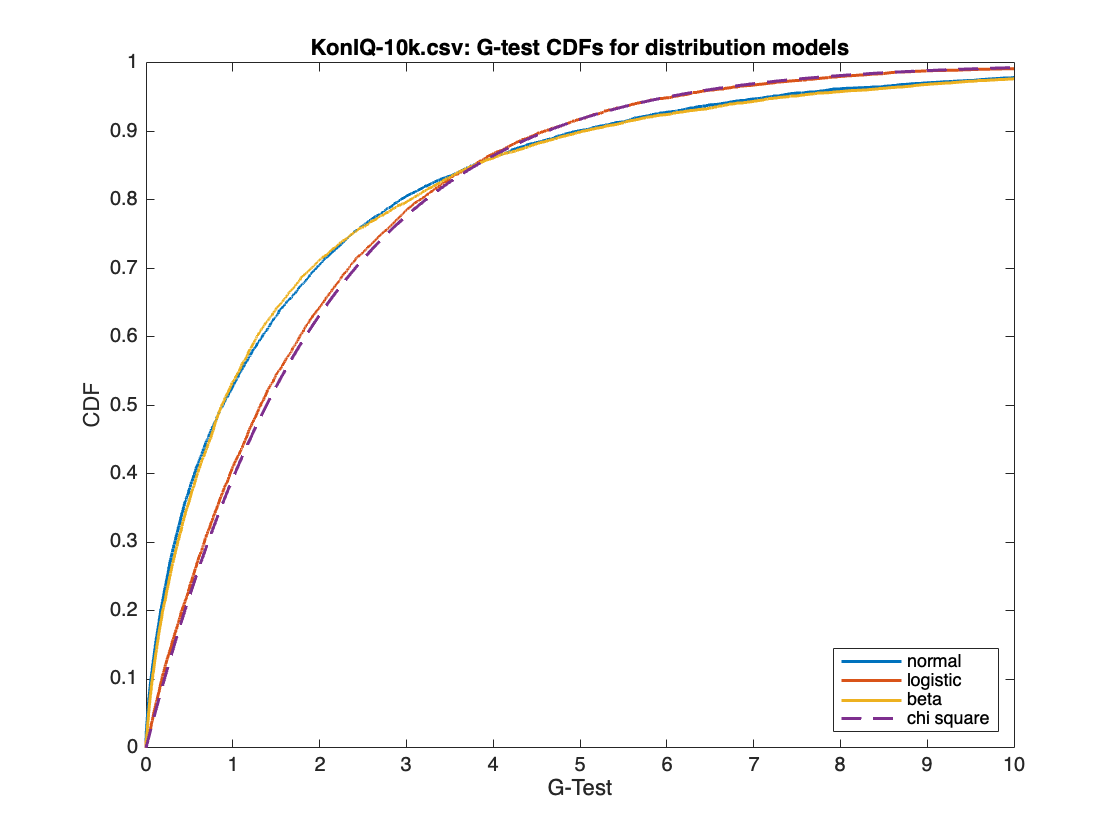

Model_plot = true;
if Model_plot
    fprintf("Critical G-test value at p = 0.05 is %5.2f\n", chi2inv(0.95,2));
    x = zeros(nmodels,n);
    y = zeros(nmodels,n);
    figure
    for model = 1:nmodels
        [x(model,:), y(model,:)] = samplecdf (gtest(model,:));
        p = plot (x(model,:), y(model,:)); hold on
        p.LineWidth = 1.5;
    end
    % also plot the chi2 distribution with 2 degrees of freedom
    p = plot (x(1,:), chi2cdf(x(1,:),2), '--'); hold on
    string = sprintf("%s: G-test CDFs for distribution models", csvfile);
    title(string)
    p.LineWidth = 1.5;
    xlabel('G-Test'); xlim([0 10]); 
    ylabel('CDF'); ylim([0 1.0]); 
    legend([dlist,"chi square"],'Location','southeast');
    hold off
end

## Solver by optimization

function [par, pvout, nll] = solve_opt (pvin, distribution)
%-----------------------------------------------------------------------
% Interior point solver fmincon from Matlab
% settings for fmincon optimization
DisplayOption = 'none';     % fminunc options: none, iter, notify, final, iter-detailed
nstimulioptions = optimoptions('fmincon');
options = optimoptions(@fmincon, ...
    'MaxIter',1000, ...
    'MaxFunEvals', 10000, ...
    'Algorithm','interior-point',...        %interior-point, sqp
    'SpecifyObjectiveGradient',false, ...
    'CheckGradients', false, ...
    'TolFun',1e-6, ...
    'TolX',1e-6, ...
    'Display', DisplayOption);
% list of constraints
A = [];
b = [];
Aeq = [];
beq = [];
nonlcon = [];
%
switch distribution
    case 'normal'
        delta = 20;
        lb = [1-delta,0];
        ub = [5+delta,100];
    case 'logistic'
        delta = 20;
        lb = [1-delta,0];
        ub = [5+delta,100];
    case 'beta'
        lb = [0,0];
        ub = [20,20];
    case 'kumaraswamy'
        lb = [0,0];
        ub = [20,20];
    case 'logit-logistic'
        lb = [0,0];
        ub = [1,20];
    case 'GSD'
        lb = [1,0];
        ub = [5,1];
end
% function to be minimized
fun = @(x)opt (x, pvin, distribution);
%
% do the optimization
% sometimes the random initial guess leads to convergence to a suboptimal
% local MLE maximum. This is detected by the check if the normalized gtest 
% (=gtest/ratings) is greater than 1. 
% In that condition, a new random initial guess is tried (up to 10 times).
ngtest = inf; iter = 1;
while ngtest > 1.0 & iter <= 10
    x0 = init_solution (distribution, pvin);
    [par,nll,exitflag,output] = fmincon(fun,x0,A,b,Aeq,beq,lb,ub,nonlcon,options);
    pvout = ACR(par,distribution) + eps;
    if exitflag <= 0
        fprintf("Exit fmincon in solve_opt (psi, rho). flag = %d\n", exitflag);
        output
        fprintf (" pvin %f %f %f %f %f    entropy %f\n", pvin, - sum(pvin.*log(pvin)));
        fprintf ("pvout %f %f %f %f %f  x-entropy %f\n", pvout, - sum(pvin.*log(pvout)));
    end
    ngtest = - 2 * (sum(pvin.*log(pvout)) - sum(pvin.*log(pvin)));       % normalized G-test
    if (iter==1 & ngtest>1)
        fprintf("Suboptimal local minimum. ngtest %.2f nll %.2f. Next: ", ngtest, nll); 
    end
    if (iter>1 & ngtest>1),
        fprintf("ngtest %.2f  nll %.2f.  Next: ", ngtest,  nll);
    elseif (iter>1 & ngtest<=1)
        fprintf("ngtest %.2f  nll %.2f. OK: Accepted (%d trials).\n", ngtest,  nll, iter);
    end
    iter = iter + 1;
end
pvout = ACR(par,distribution) + eps;
end

## Setup random initial conditions

function x0 = init_solution (distribution, pvin)
switch distribution
    case 'normal'
        x0(1) = 1 + 4*rand;
        x0(2) = 3*rand;
    case 'logistic'
        x0(1) = 1 + 4*rand;
        x0(2) = 3*rand;
    case 'beta'
        x0(1) = rand;
        x0(2) = rand;
    case 'kumaraswamy'
        x0(1) = rand;
        x0(2) = rand;
    case 'logit-logistic'
        x0(1) = rand;
        x0(2) = 3*rand;
    case 'GSD'
        [x0(1), ~, x0(2)] = SOS(pvin);
end
end

## Loss function

function nll = opt (x, pv, distribution)
% x = 2d parameter vector
% pv = prob vector
model = ACR(x,distribution)+eps;  % add eps to avoid log(0);
nll = -sum(pv.*log(model));
end

## ACR probability distribution

function p = ACR(x,distribution)
% x = 2d parameter vector
switch distribution
    case 'normal'
        thresholds = [1.5,2.5,3.5,4.5];
        pcdf = normcdf(thresholds,x(1),x(2));
    case 'logistic'
        thresholds = [1.5,2.5,3.5,4.5];
        pcdf = logisticcdf(thresholds,x(1),x(2));
    case 'beta'
        thresholds = [0.2,0.4,0.6,0.8];
        pcdf = betacdf(thresholds,x(1),x(2));
    case 'kumaraswamy'
        thresholds = [0.2,0.4,0.6,0.8];
        pcdf = kumaraswamycdf(thresholds,x(1),x(2));
    case 'logit-logistic'
        thresholds = [0.2,0.4,0.6,0.8];
        pcdf = logitlogisticcdf(thresholds,x(1),x(2));
    case 'GSD'
        p = getGSD(x(1),x(2));
        return;
    otherwise
        warning('Unexpected distribution type in ACR(x,distributon).')
end
p(1) = pcdf(1) - 0;
p(2) = pcdf(2) - pcdf(1);
p(3) = pcdf(3) - pcdf(2);
p(4) = pcdf(4) - pcdf(3);
p(5) =       1 - pcdf(4);
end

## $(\psi,var,\rho)$ for a probability vector (from the SOS hypothesis) 

function  [psi, var, rho] = SOS(p)
% Input p = probability row vector of dimension 5
psi = p*[1;2;3;4;5];                            % mean
var = p*(([1;2;3;4;5]-psi).^2);                 % variance
vmin = (ceil(psi)-psi)*(psi-floor(psi));        % minimal variance
vmax = (psi-1)*(5-psi);                         % maximal variance
if (vmax > vmin)
    rho = (vmax - var)/(vmax - vmin);           % rho = 1 -> minimal variance
else
    rho = 0.5;
end
end

## Compute cumulative distribution function from random samples

function [x, cdf] = samplecdf (data)
% Compute cumulative distribution function for a set of numbers
% Input: data = row vector of real numbers
% Output: cdf as  cdf(x) = proportion of data <= x
x = sort(data);
cdf = (1:length(data))/length(data);
end

## Kumaraswamy distribution

Support on [0,1] with cdf $1 -(1-x^a)^b$

function cdf = kumaraswamycdf(x,a,b)
cdf = 1 - (1-x.^a).^b;
end

## Logistic distribution

function cdf = logisticcdf(x,mu,s)
cdf = 1./(1 + exp(-(x-mu)./s));
end

## Logit-Logistic distribution

function cdf = logitlogisticcdf(x,mu,s)
cdf = 1./(1 + ((mu*(1-x))./(x*(1-mu))).^(1/s));
end

## HmaxPV - Maximum entropy probability vector

function [par, pvout, nll] = HmaxPV (pvin)
%-----------------------------------------
% This function outputs psi (mean) and rho (complementary normalized variance) 
% of the maximum entropy probabilty distribution pvout which minimizes
% the negative log-likelihood for the input distribution pvin.
% It also computes the corresponding maximum entropy probability
% distribution pvout.
% By means of a theorem (not contained in the paper), the mean and complementary normalized
% variance of the solution are equal to those of the input distribution (oracle).
% So pvout has the same mean and variance as pvin.
% The main part of this function therefore computes the maximum entropy
% probabilty distribution for the given input mean and complementary normalized
% variance.

[psi, ~, rho] = SOS(pvin);
par = [psi, rho];      % maximum entropy model parameters are psi and rho (Oracle)

% Interior point solver fmincon from Matlab
% settings for fmincon optimization
DisplayOption = 'none';     % fminunc options: none, iter, notify, final, iter-detailed
nstimulioptions = optimoptions('fmincon');
options = optimoptions(@fmincon, ...
    'MaxIter',500, ...
    'MaxFunEvals', 10000, ...
    'Algorithm','interior-point',...        %interior-point, sqp
    'SpecifyObjectiveGradient',true, ...
    'CheckGradients', false, ...
    'TolFun',1e-8, ...
    'TolX',1e-8, ...
    'ConstraintTolerance', 1e-5, ...
    'Display', DisplayOption);
% lower and upper bounds
lb = [0,0,0,0,0];
ub = [1,1,1,1,1];
% list of linear constraints
A = [];
b = [];
Aeq = [1,1,1,1,1];
beq = [1];
% function for nonlinear equality constraints
mycon = @(x)constraints(x, psi, rho);

% do the optimization
fun = @(x)optH(x);                      % negative entropy shall be minimized
p0 = diff([0, sort(rand(1,4)), 1]);     % initialization: random ACR probability vector
% Another good initialization is p0 = [0.2, 0.2, 0.2, 0.2, 0.2];
% Initializations near the boundary of the domain may fail to give convergence.
[pvout,fval,exitflag,output] = fmincon(fun,p0,A,b,Aeq,beq,lb,ub,mycon,options);
if exitflag <= 0
    fprintf("Exit fmincon in HmaxPV (psi, rho). flag = %d\n", exitflag);
    output
    fprintf (" pvin %f %f %f %f %f    entropy %f\n", pvin, - sum(pvin.*log(pvin)));
    fprintf ("pvout %f %f %f %f %f  x-entropy %f\n", pvout, - sum(pvin.*log(pvout)));
end
pvout = pvout + eps;                    % add machine unit to prevent log(0)
nll = - sum(pvin.*log(pvout));
end

function analyse (p, text)              % only for debugging
    [psi, ~, rho] = SOS(p);
    [neg_entropy, grad] = optH (p);
    fprintf ("%s psi/rho %7.5f %7.5f  p %f %f %f %f %f  entropy  %f\n", text, psi, rho, p, -neg_entropy);
end

function [c, ceq] = constraints (p, psi_, rho_)
% c is an array of nonlinear inequality contraints
c = [];
% ceq is an array of two nonlinear equality contraints
% ceq(1) and ceq(2) ensure that p has the required psi and rho
[psi, ~, rho] = SOS(p);
ceq(1) = psi_ - psi;
ceq(2) = rho_ - rho;
end

function [neg_entropy, grad] = optH (p)
% negative entropy to be minimized to obtain maximum entropy
p0 = p(p>0);
neg_entropy = sum(p0.*log(p0));         % negative entropy
if nargout > 1                          % gradient required (column vector!)
    grad = (log(p+eps)+1)';
end
end

## GSD - Table lookup for the GSD

The GSD model is comuted from a large table of precomputed models 

function setGSD (csvfile)
%-----------------------------------------------------------------------
global GSDarray;
% Interpretation of GSDarray(i,j,k)
% GSDarray(1,j,k) = psi = 1 + (k-1)*4/1000
% GSDarray(2,j,k) = rho = (j-1)*100
% GSDarray(3:7,j,k) = pv(1:5) for parameters (psi,rho)
T = readtable(csvfile);                     % read csv file with GSD table info
T(1,:) = [];                                % remove table header row
GSDarray = table2array(T)';
GSDarray = reshape(GSDarray,7,101,[]);      % GSDarray has 2+5 columnlength, 101 rowlength, and 1001 pages
end

function pv = getGSD (psi, rho)
%-----------------------------------------------------------------------
global GSDarray;
if ~isreal(psi) || ~isreal(rho)
    psi,rho
end

if (psi<1 || psi>5 || rho<0 || rho>1)
    fprintf ("Error in getGSD %f %f \n", psi, rho);
    psi = min([max([psi,1]),5]);
    rho = min([max([rho,0]),1]);
end
kfloat = 1 + 250*(psi-1);
if (kfloat < 1)
    fprintf("getGSD: kfloat < 1. psi %f\n", psi);
    kfloat = 1;
end
k = (floor(kfloat)); dk = kfloat - k;
if (k==1001)
    k = 1000; dk = 1.0;
end
jfloat = 1 + 100*rho;
if (jfloat < 1)
    fprintf("getGSD: jfloat < 1. rho %f\n", psi);
    jfloat = 1;
end
j = (floor(jfloat)); dj = jfloat - j;
if (j==101)
    j = 100; dj = 1.0;
end
if (j<1)
    fprintf("getGSD: j < 1.  %d\n", j);
    j = 1;
end

%pv = GSDarray(3:7,j,k);             % use this to turn off bilinear interpolation
pv = (1-dj)*(1-dk)*GSDarray(3:7,j,k) + dj*(1-dk)*GSDarray(3:7,j+1,k) + ...
    (1-dj)*dk*GSDarray(3:7,j,k+1) + dj*dk*GSDarray(3:7,j+1,k+1);
pv = pv'+eps;                        % returns a row vector with bilinear interpolation
end